Defining necessary variables and opening our group folder

% ok lets gooooooooooooo!!!!!

%Opening folder and checking if its properly open
Imfolder = 'CV_zebracrossing_images';
if ~isfolder(Imfolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', Imfolder);
    uiwait(warndlg(errorMessage));
    return;
end

% Get a list of all image files in the folder
imageFiles = dir(fullfile(Imfolder, '*.jpg'));

%Variable declaration
imnum = numel(imageFiles);
stockImages = cell(1, imnum);
images = cell(1, imnum);
imheight = zeros(1, imnum);
imcropped = cell(1, imnum);
imgray = cell(1,imnum);
binim = cell(1,imnum);
edgedetected = cell(1,imnum);
imageOverlay = cell(1,imnum);
detectedCrossing = zeros(1,imnum);

This is the code for the zebra crossing detection that also sends pictures with zebra crossing to the classification algorithm.

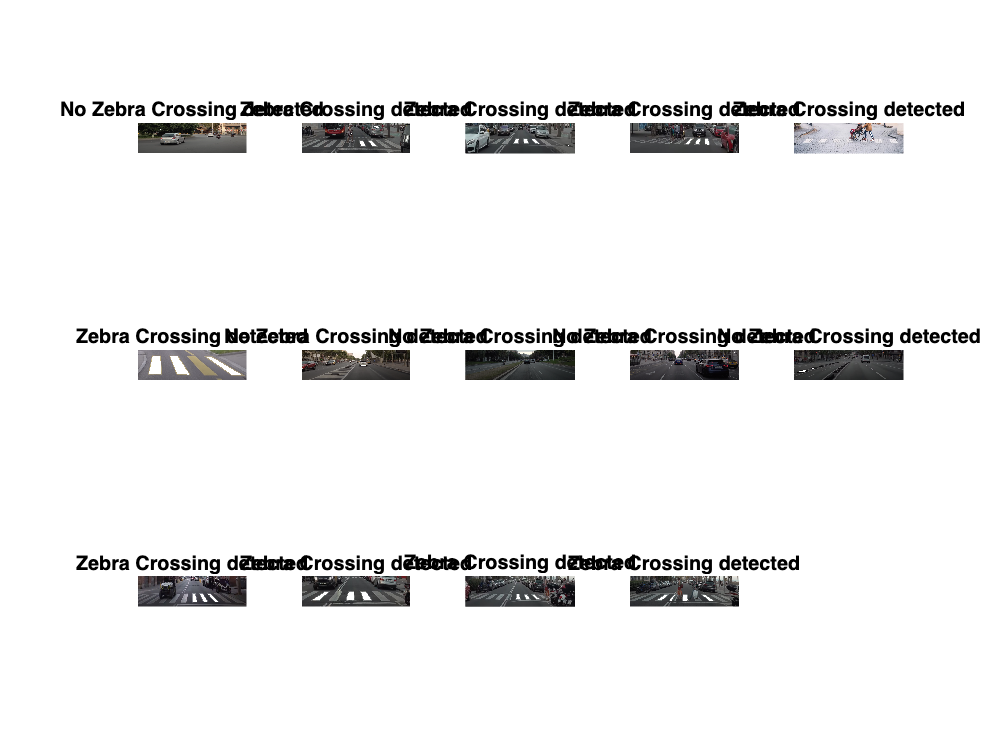

% Create a folder for storing the processed images
outputFolder = 'ready_for_classification';
if ~isfolder(outputFolder)
    mkdir(outputFolder);
end

for idx = 1:imnum
    %read all images
    filename = fullfile(Imfolder, imageFiles(idx).name);
    stockImages{idx} = imread(filename);
    %resize all images to one size for optimal cropping
    images{idx}=imresize(stockImages{idx},[300,600]);
    imcropped{idx} = imcrop(images{idx}, [0.5 133 600 167]);
    %create a grayscale image
    imgray{idx} = im2gray(imcropped{idx});

    %apply edgedetection using canny method and store them in one array
    edgedetected{idx} = edge(imgray{idx}, 'canny');

    %repair the broken edges using a morph function
    morphedLines = bwmorph(edgedetected{idx}, 'bridge');

    %find boundaries and store their coordinates under B, label all
    %connected pixels in the matrix L.
    %found.
    [B, L] = bwboundaries(edgedetected{idx});

    %Create a RGB image with alle the found objects
    RGB = label2rgb(L);

    binaryImage = RGB(:,:,1) > 230; % Adjust the Threshold as needed

    %store the adjustet binary images under OriginalImage and store the
    %inverted picture as SwitchedImage
    OriginalImg = binaryImage;
    SwitchedImage = ~binaryImage;

    %calculate percentage of white pixels in the pictures
    numOnes = sum(~binaryImage(:) == 1);
    totalElements = numel(~binaryImage);
    percentageOnes = (numOnes / totalElements) * 100;

    %use a self determint threshold to classify the images
    if percentageOnes > 11
        %zebracrossing detected
        detectedCrossing(idx) = 1;
        % Define the filename for the saved image
        [~, imageName, imageExt] = fileparts(imageFiles(idx).name);
        newFileName = fullfile(outputFolder, strcat(imageName, '_processed', imageExt));
        % Save the resized image
        imwrite(images{idx}, newFileName);
    else
        %No zebracrossing detected
        detectedCrossing(idx) = 0;
    end

    %Creating structuring Element SE
    SE = strel("disk",5);

    %Morphological Erosion and Image Overlay
    % Perform erosion on the binary image
    BW1 = imerode(SwitchedImage,SE);
    % Replicate binary image into a 3D grayscale overlay
    BW1_rgb_1 = repmat(BW1, [1 1 3]);
    % Convert the overlay to double precision
    BW1_double = double(BW1_rgb_1);
    % Create an overlay highlighting detected zebra crossing
    imageOverlay{idx} = imcropped{idx} + uint8(BW1_double) .* 255;


end
%Display all Pictures with detected zebracrossings highlighted in one figure with our classification as a Title
for j = 1:imnum
    figure(1);
    subplot(3, 5, j);
    imshow(imageOverlay{j});
    if detectedCrossing(j) == 1
        title("Zebra Crossing detected");
    else
        title("No Zebra Crossing detected");
    end
end

Here you can find the code for the deeplearning net and the classification.

% Load pre-trained Faster R-CNN model for people detection
detector = peopleDetectorACF;

% Specify binary classification CNN model architecture (customize as needed)
layers = [
    imageInputLayer([300 600 3])
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

% Specify training options
options = trainingOptions('sgdm', 'MaxEpochs', 20, 'MiniBatchSize', 32, 'InitialLearnRate', 1e-3);

binaryLabels = categorical([0,1,1,0,0,1,1,0,1,0,1,1,0,0,0,1,0,1,0,0,0,0,1,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,0,1,1,0,0,1,1,1,0,1,0,1]);
% Train the binary classification model
% Assuming binaryLabels is a vector of binary labels (0 or 1)
data = imageDatastore('CV_resized_images', 'Labels', binaryLabels);

binaryClassifier = trainNetwork(data, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |       56.25% |       0.8496 |          0.0010 |
|      20 |          20 |       00:01:45 |      100.00% |   0.0000e+00 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


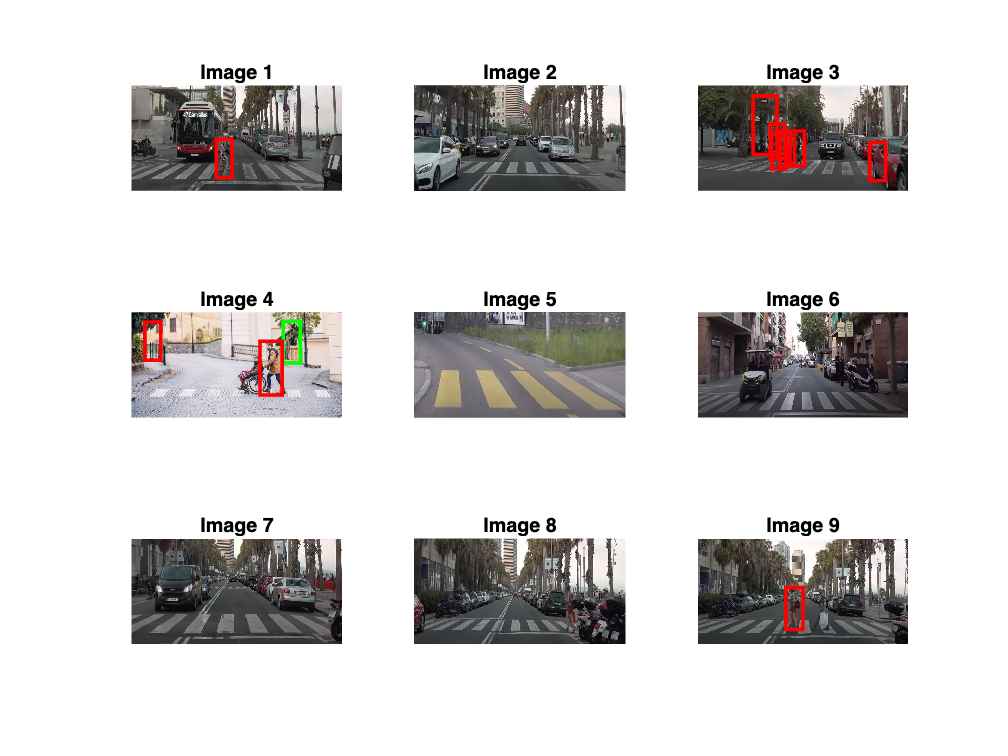




% Define the folder containing the processed images
processedFolder = 'ready_for_classification';
% Get a list of all image files in the folder
processedImageFiles = dir(fullfile(processedFolder, '*.jpg'));

% Create a new figure for displaying all processed images
figure(2);

for idx = 1:numel(processedImageFiles)
    % Read each processed image
    filename = fullfile(processedFolder, processedImageFiles(idx).name);
    img = imread(filename);

    % Use the object detector to find people in the image
    [bboxes, scores] = detect(detector, img);

    subplot(ceil(sqrt(numel(processedImageFiles))), ceil(sqrt(numel(processedImageFiles))), idx);
    imshow(img);
    title(['Image ', num2str(idx)]);

    for i = 1:size(bboxes, 1)
        % Extract and resize the region containing a person
        personImage = imcrop(img, bboxes(i, :));
        personImage = imresize(personImage, [300, 600]);

        % Use the binary classifier to determine if the person is on a zebra crossing
        prediction = classify(binaryClassifier, personImage);

        % Display the results
        hold on;
        if prediction == categorical(1)
            % Person is on a zebra crossing
            rectangle('Position', bboxes(i, :), 'EdgeColor', 'g', 'LineWidth', 2);
        else
            % Person is not on a zebra crossing
            rectangle('Position', bboxes(i, :), 'EdgeColor', 'r', 'LineWidth', 2);
        end
        hold off;
    end
end